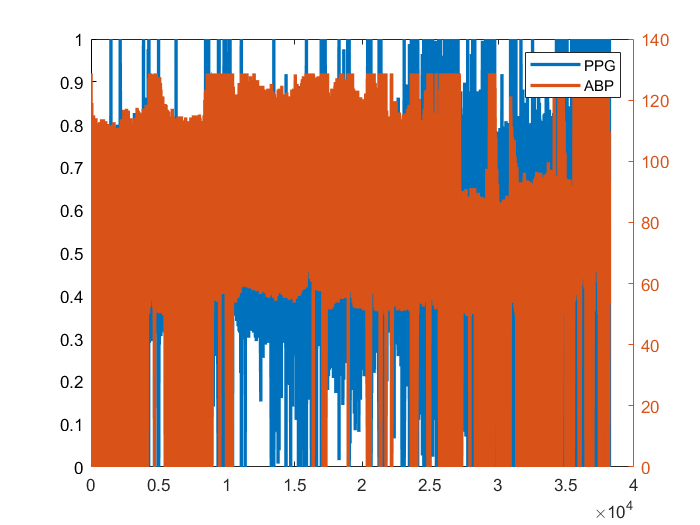

%EXAMPLE IMPORT AND PLOT
record_name = '3000063';
number = '0020';

folder = record_name(1:2);

%data = importdata("../physionet.org/textdata/"+record_name+"_"+number+".txt")

data = cell2mat(textscan( fopen("../physionet.org/textdata/"+record_name+"_"+number+".txt"), ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
Fs=125;
signal = data(:,2:3);
tm = data(:,1);

start_disp = 1;%round(length(tm)/4);
end_disp = length(tm);%%start_disp+3*Fs;
clf
 plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
hold on
yyaxis right
plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
legend("PPG", "ABP")

%FILTERING

%file size thresholding already performed in Python scraper and conversion tool

% Following MIMIC cleaning process in Slapnicar et al. Blood Pressure Estimation from Photoplethysmogram 
%       Using a Spectro-Temporal Deep Neural Network


% Get list of files 
% normalise to zero mean unit variance -> 4th order Butterworth BPF with 0.5 Hz and
% 8Hz cutoffs
orig_file_dir = "../physionet.org/textdata/";
abp_ann_dir = '../physionet.org/abp_ann/';

fileList = dir(orig_file_dir+"*.txt") %only consider all text files

fileList = 70×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


cleaned_file_dir = "../physionet.org/cleaned_data/";
if ~isfolder(cleaned_file_dir)
    mkdir(cleaned_file_dir)
end

regioned_file_dir = "../physionet.org/regioned_data/";
if ~isfolder(regioned_file_dir)
    mkdir(regioned_file_dir)
end


%BPF transfer function
Fs = 125;
% [filt_num, filt_den] = butter(2, 2*pi.*[0.25 20]/(2*pi*Fs),'bandpass')
[filt_num, filt_den] = butter(2, 2*pi.*20/(2*pi*Fs),'low')

filt_num =     0.0461    0.0923    0.0461


filt_den =     1.0000   -1.3073    0.4918


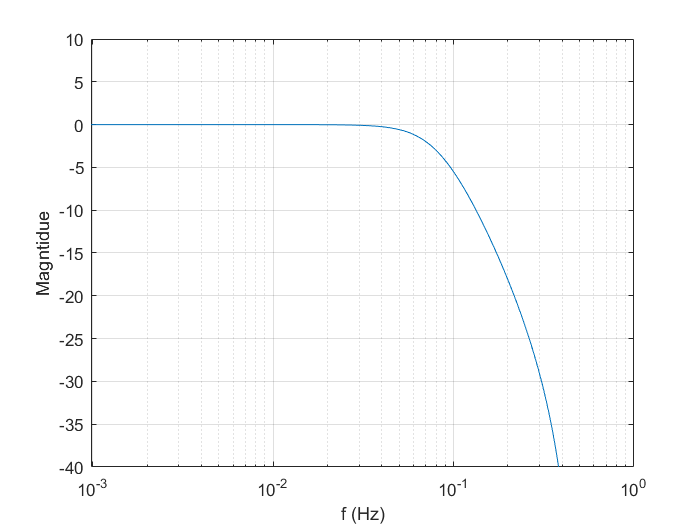

[h,w] =freqz(filt_num, filt_den);
clf
semilogx(w./(2*pi),20.*log10(abs(h)));
ylim([-40,10]);
grid on
xlabel('f (Hz)')
ylabel('Magntidue')




parfor idx = 1:length(fileList)
    
     dataFile = fopen(orig_file_dir + fileList(idx).name);
     data = cell2mat(textscan( dataFile, ...
         '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
     fclose(dataFile);
     
     abpAnnFile = fopen([abp_ann_dir fileList(idx).name(1:end-4) '_abp.txt']);
     locOfAbpBeats = cell2mat(textscan( abpAnnFile, ...
         '%*s %d %*s %*d %*d %*d'));
     fclose(abpAnnFile);
     
%      discard_file = false;
     
     data(:,2) = filter(filt_num, filt_den, data(:,2));
     data(:,3) = filter(filt_num, filt_den, data(:,3));
     
     invalidABPRegions = findInvalidABPRegions(data(:,2), locOfAbpBeats);
     
     
     abp_flats = findFlatRegions(data(:,2), 30);
     ppg_flats = findFlatRegions(data(:,3),30);
     all_invalid = abp_flats | ppg_flats | invalidABPRegions;
     
     minSegmentLength = 7500; %corresponds to 1 minute at 125 Hz
     [segmentedSignals, numSegments] = removeInvalidFromSignal(all_invalid, minSegmentLength, data(:,1), data(:,2), data(:,3));
     
     for i=1:numSegments
         out_data = [segmentedSignals{i}{1}{:}, segmentedSignals{i}{2}{:},segmentedSignals{i}{3}{:} ];
         outPath = regioned_file_dir+fileList(idx).name(1:end-4) + "-"+num2str(i)+".txt";
         writematrix(out_data, outPath , 'Delimiter', 'tab');
     end
     
%      for i=2:3
%          if discard_file
%              continue;
%          end
%          
%         discard_file = ~validateData(data(:,i));
%         if discard_file
%             continue;
%         end
%         
%         data(:,i) = normalize(data(:,i));
%     
%         data(:,i) = filter(bpf_num, bpf_den, normalize(data(:,i)));
%      end
    
     
%      if ~discard_file
%          fprintf('Writing cleaned %s to folder \n', fileList(idx).name);
%          writematrix(data, cleaned_file_dir+fileList(idx).name, 'Delimiter', 'tab')
%      else 
%          fprintf('Marked %s as junk \n', fileList(idx).name);
%      end
%    
end


     
% *********** ignore ******************
% 
% 
% record_name = '3600293';
% number = '0004';
% 
% folder = record_name(1:2);
% 
% data = importdata("../physionet.org/textdata/"+record_name+"_"+number+".txt")

data = struct with fields:
          data: [122258×3 double]
      textdata: {242×3 cell}
    colheaders: {'          1.928'  ' 90.117'  '      -'}


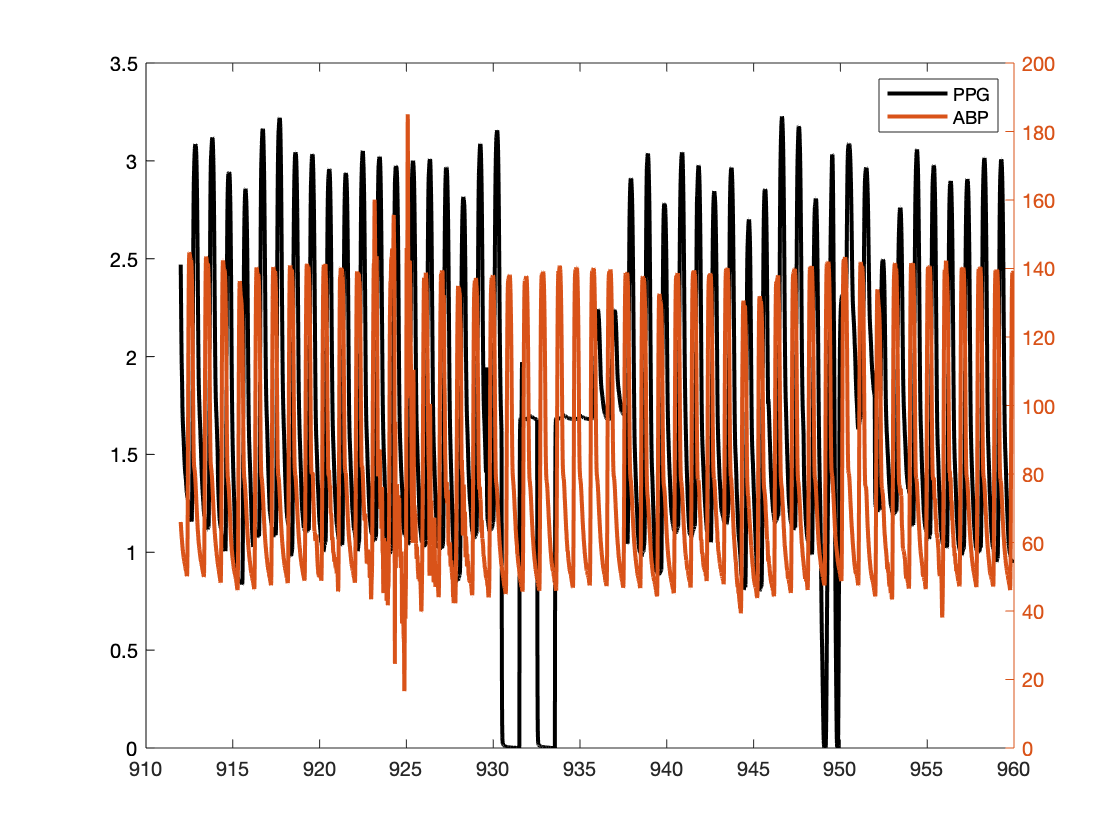

% 
% data = cell2mat(textscan( fopen("../physionet.org/textdata/"+record_name+"_"+number+".txt"), ...
%          '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));
% 
% data = data(114001:120000, :);
% Fs=125;
% signal = data(:,2:3);
% tm = data(:,1);
% 
% start_disp = 1;%round(length(tm)/4);
% end_disp = length(tm);%%start_disp+3*Fs;
% clf
%  plot(tm(start_disp:end_disp), signal(start_disp:end_disp,2), 'LineWidth', 2)
% hold on
% yyaxis right
% plot(tm(start_disp:end_disp,1), signal(start_disp:end_disp,1), 'LineWidth',2)
% legend("PPG", "ABP")

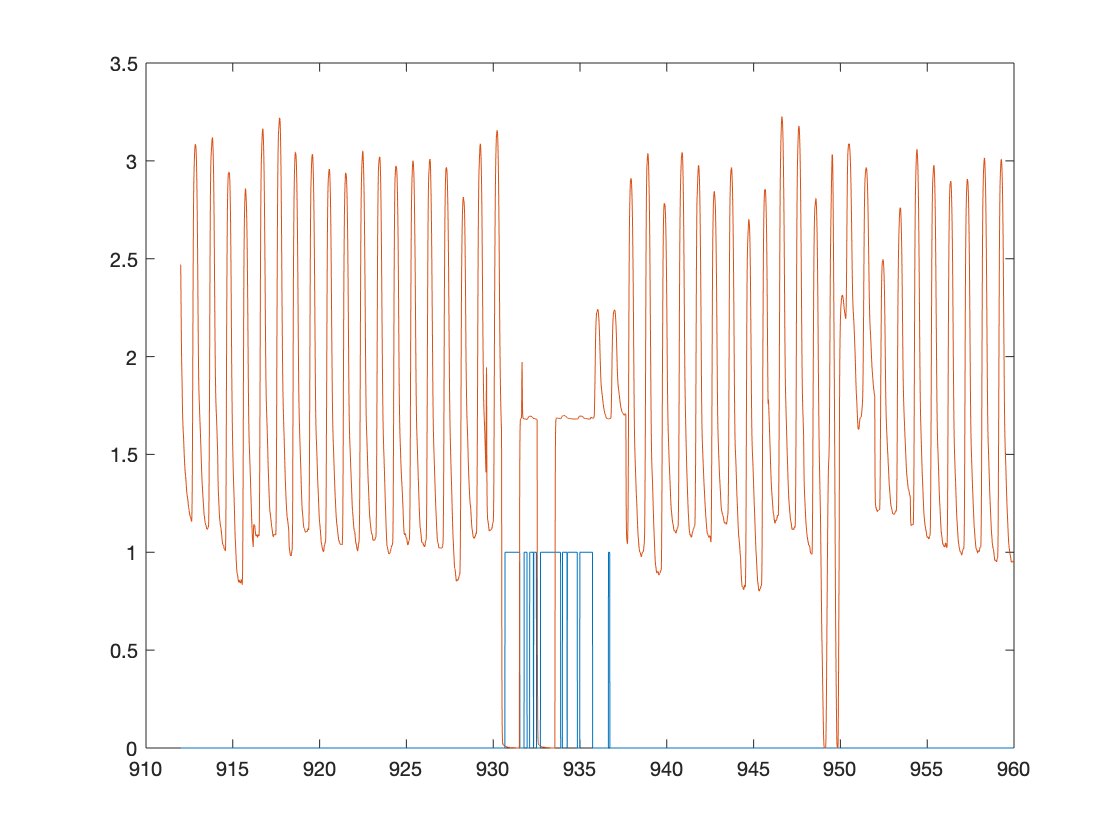

% 
% data = signal(:,2);
% 
% tol = 1e-4;
% diff_check = abs(diff(data))<tol ;
% multiple_pts = 20;
% invalid_portions =  [1; ( movmean(diff_check, multiple_pts-1) < 1)];
% 
% clf
% plot(tm, movmean([0;diff_check],30)>0.55)
% hold on
% plot(tm, data)

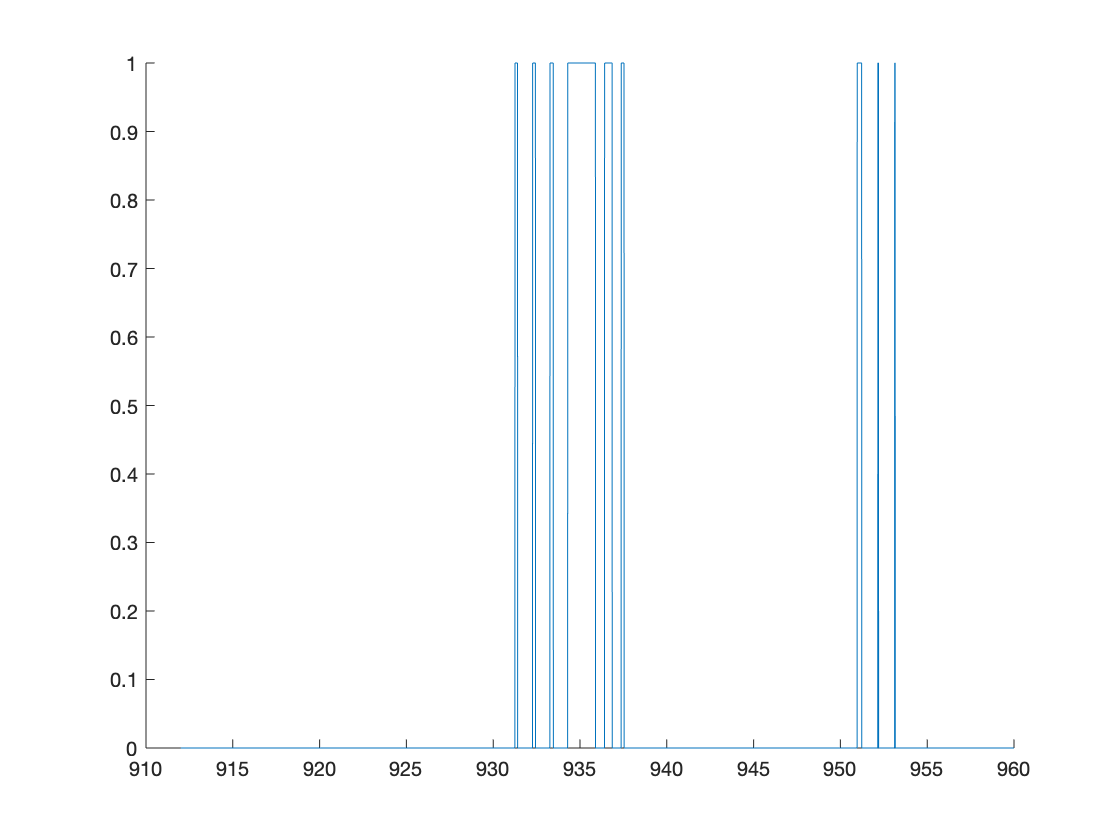

% 
% 
% 
% [num, den] = butter(4, 2*pi.*3.5/(2*pi*Fs),'high');
% clf
% d = normalize(abs(filter(num, den, data)));
% % plot(tm, d)
% hold on
% plot(tm,movmean(d,30)<-0.9)



% norm_data = normalize(data(:,3));
% clf
% %flat regions will have a variance of approx 0
% moving_variance = movvar(norm_data, 50);
% %then find regions with consecutively low variances
% invalid_regions = movmean(moving_variance <0.01, 200) > 0.4;
% %use |diff| to find changes between okay regions and junk (regions between
% %two spikes are junk)
% segment_indices = [1;find( [0; abs(diff(invalid_regions))] ); length(data)]

segment_indices =            1
        2317
        2331
        2371
        3019
        6000


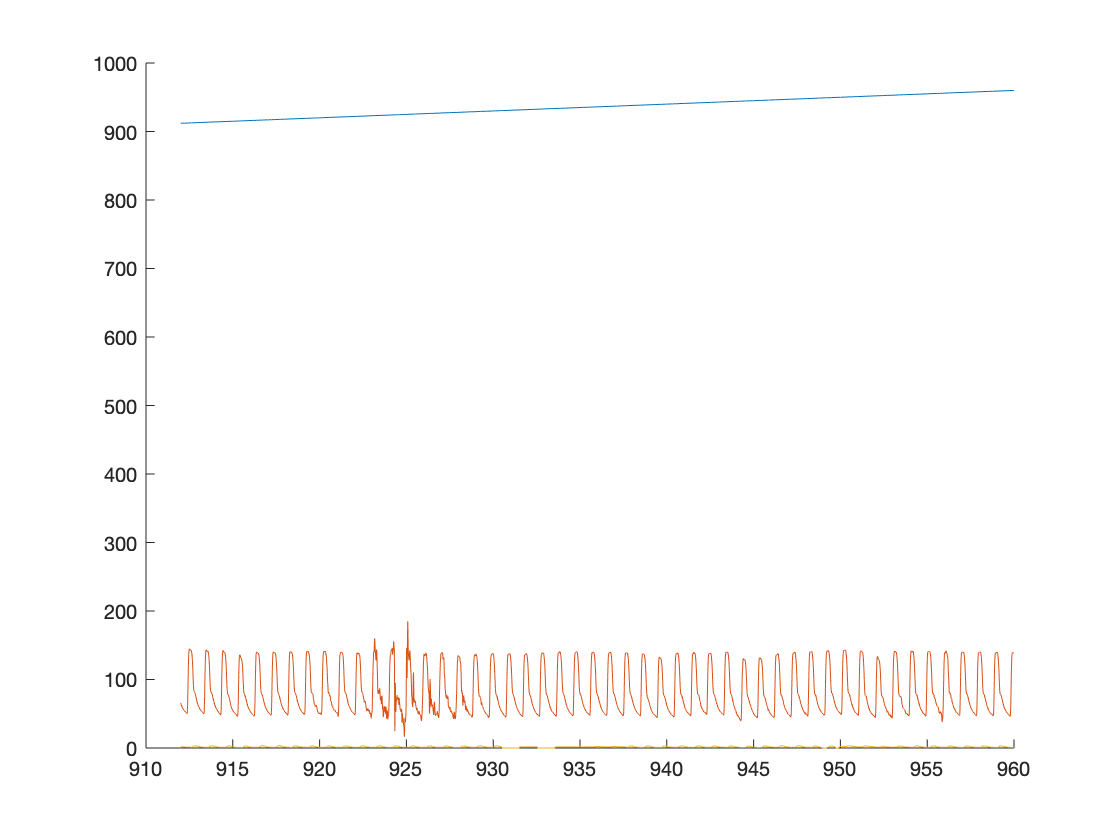

% % plot(tm, [0;abs(diff(invalid_regions))] )
% hold on
% plot(tm, data)